## Aperture (apodization)

The shape of the aperture can have a significant impact on the image.  Some of the famous closed form results are for diffraction limited circular apertures (Airy disk). In this script we will calculate diffraction limited images with different aperture shapes.

ieInit % Start ISETCam

SceneFirst, create a high dynamic range scene.  This will reveal the details of the point spread clearly.

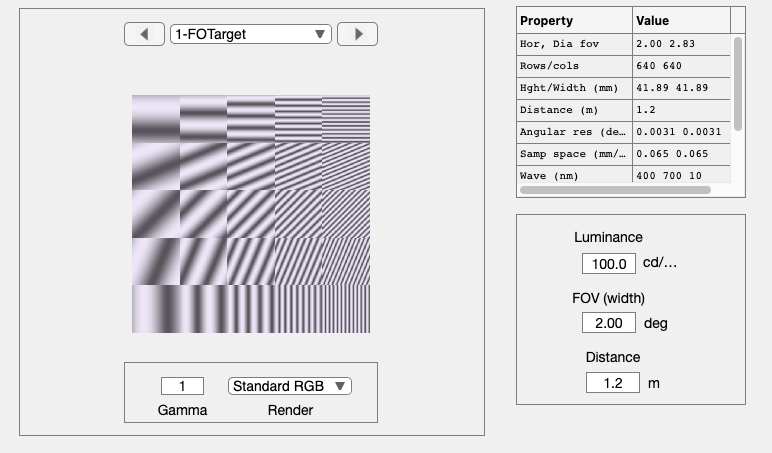

% scene = sceneCreate('sweepfrequency',512,16)
parms.angles = linspace(0,pi/2,5); parms.freqs =  [1,2,4,8,12];
parms.blockSize = 128; parms.contrast = .8;
scene = sceneCreate('frequency orientation',parms);
scene = sceneSet(scene,'fov',2);
sceneWindow(scene);

Now create an oi, and notice that we can ask for the wavefront structure to be returned at the time of creation.

[oi,wvf] = oiCreate('wvf');

This sets the sample density of the aperture image. We use a high sampling density to show the details clearly.

wvf = wvfSet(wvf,'npixels',512);

## Rectangular aperture

How do we set the absolute size of the aperture?  Smaller and smaller should be increasingly blurred by diffraction.

Notice that the top row is higher contrast than the bottom row.  This should reverse if I use [1 3]

aspectRatio = [3 1];   % (row,col), which is (y,x)
aperture = wvfAperture(wvf,'shape',...
    'rectangle','aspect ratio',aspectRatio, ...
    'dot mean',0,'dot sd',0,...
    'line mean',0,'line sd',0);

oi = oiCompute(oi, scene,'crop',true,'pixel size',1e-6,'aperture',aperture);
oi = oiAdjustIlluminance(oi, 100);


## Show the image and the point spread

You can see that the contrast in the top row is higher than the contrast in the bottom row. That is because the shape of the rectangular aperture is wide, and thus there is less diffraction-related blurring in the y-direction.  I run it the other way below, just to be pedantic.

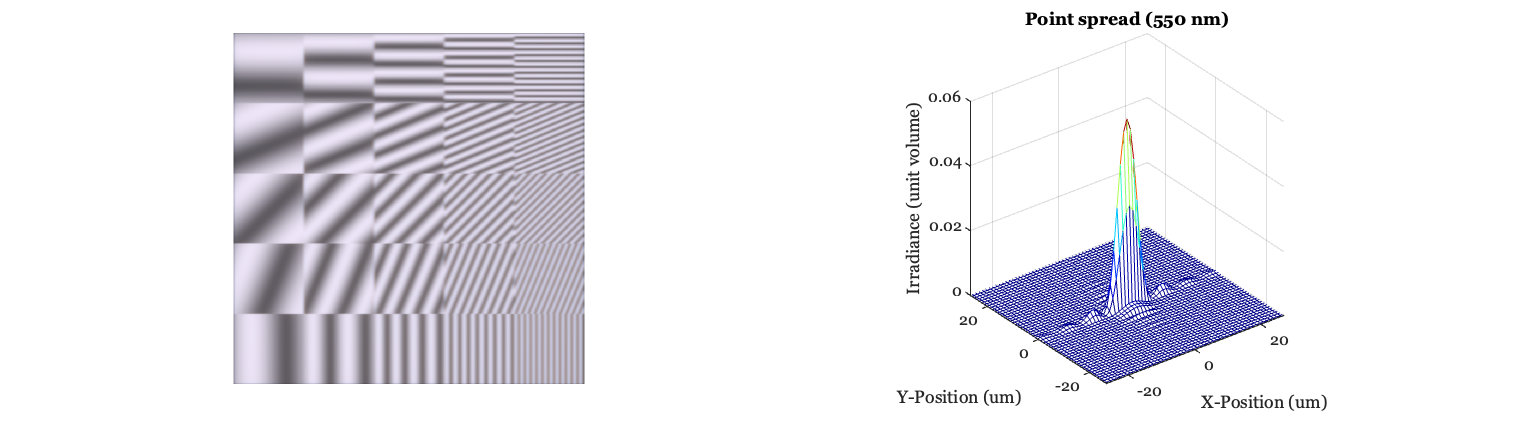

img = oiGet(oi,'rgb');
figHdl = ieFigure([],'wide');
tiledlayout(1,2); 
nexttile; imshow(img,'InitialMagnification',100);
nexttile; oiPlot(oi,'psf',[],figHdl); axis square

## Flip the aspect ratio

When we make the aspect ratio reverse, the bottom row has higher contrast.

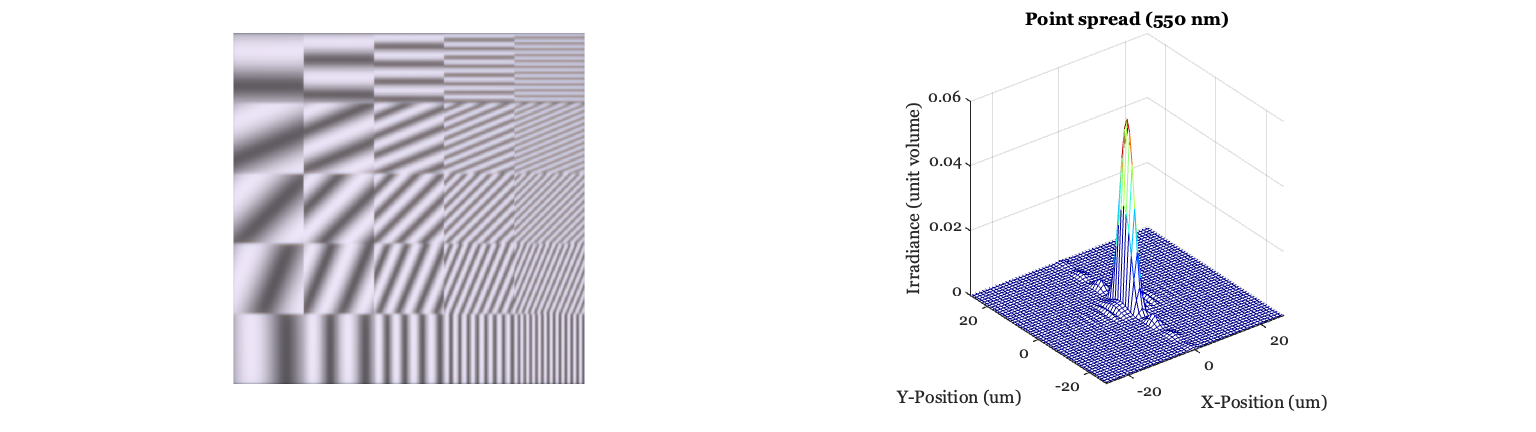

aspectRatio = [1,3];
aperture = wvfAperture(wvf,'shape',...
    'rectangle','aspect ratio',aspectRatio, ...
    'dot mean',0,'dot sd',0,...
    'line mean',0,'line sd',0);

oi = oiCompute(oi, scene,'crop',true,'pixel size',1e-6,'aperture',aperture);
oi = oiAdjustIlluminance(oi, 100);

img = oiGet(oi,'rgb');
figHdl = ieFigure([],'wide');
tiledlayout(1,2); 
nexttile; imshow(img,'InitialMagnification',100);
nexttile; oiPlot(oi,'psf',[],figHdl); axis square

%{
fname = fullfile(fiseRootPath,'chapters','images','optics','06-geometric','pinhole-shape-rectangle.png');
exportgraphics(gcf,fname);
%}

## Regular polygon apertures

Next, we create apertures that are regular polygons, but different numbers of sides.  Zero means a circular shape.  I added some dust and scratches to the aperture to make the rendering a bit more realistic.  The image itself is very high dynamic range, but rendered using an HDR algorithm to fit onto the screen nicely.  This effect is called 'flare' (see isethdrsensor).

scene = sceneCreate('hdr image',...
    'dynamic range',5,...
    'patch shape','circle','npatches',5,'patch size',10);

nsides = [4 6 8 0];   % 0 means a circular shape.
img = cell(numel(nsides),1);
sensor = [];

for ii = 1:numel(nsides)
    [aperture, params] = wvfAperture(wvf,'nsides',nsides(ii),...
        'dot mean',10, 'dot sd',5, 'dot opacity',0.5,'dot radius',5,...
        'line mean',10, 'line sd', 5, 'line opacity',0.5,'linewidth',2);

    oi = oiSet(oi,'fnumber',1.5);
    oi = oiSet(oi,'focal length',4.38e-3,'m');

    oi = oiCompute(oi, scene,'crop',true,'pixel size',3e-6,'aperture',aperture);

    oi = oiAdjustIlluminance(oi, 100);
    
    % We visualize the result in the image processor window. This is just
    % to show off - I could have stopped at the oi. But I want you to know
    % that we do simulate sensors and image processing.
    if isempty(sensor)
        % First time through, create a sensor using this function.  We
        % could have created one of many different sensors, but this one is
        % a simple, default that matches the spatial resolution of the oi.
        [ip,sensor] = piRadiance2RGB(oi,'etime',1/10);
    else
        % Second and other times, use the sensor we created
        sensor = sensorCompute(sensor,oi);
        ip = ipCompute(ip,sensor);
    end

    % Save the rendered image.
    img{ii} = ipGet(ip,'srgb');    
end


## The HDR rendering

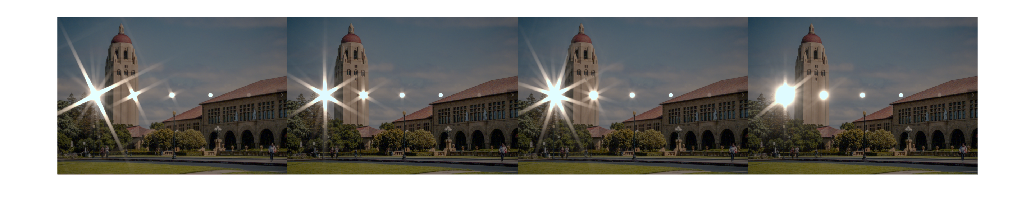

ieFigure([],'wide');
montage(img,'Size',[1, numel(nsides)]);

%{
fname = fullfile(fiseRootPath,'chapters','images','optics','06-geometric','pinhole-shape-hdr.png');
exportgraphics(gcf,fname);
%}